clear; clc; close all;
%% 1. PARÁMETROS DE FRECUENCIA Y GEOMETRÍA
c = 299792458;                 % Velocidad de la luz (m/s)
f_central = 2442e6;            % Frecuencia central de diseño ISM (2.442 GHz)
lam = c / f_central;           % Longitud de onda (~0.1228 m)
w = 0.002;                     % Ancho/diámetro del hilo (2 mm)

%% 2. BARRIDO DE LONGITUD Y CÁLCULO DE FRECUENCIA DE RESONANCIA
% Rango de prueba de la longitud del dipolo (desde 0.44*lambda hasta 0.48*lambda)
factores = linspace(0.44, 0.48, 21);
L_vector = factores * lam;
reactancias = zeros(size(factores));
f_res_vector = zeros(size(factores));
f_rang_sweep = linspace(0.8*f_central, 1.2*f_central, 100);

fprintf('Ejecutando barrido para sintonizar resonancia a %.2f MHz...\n', f_central/1e6);

Ejecutando barrido para sintonizar resonancia a 2442.00 MHz...


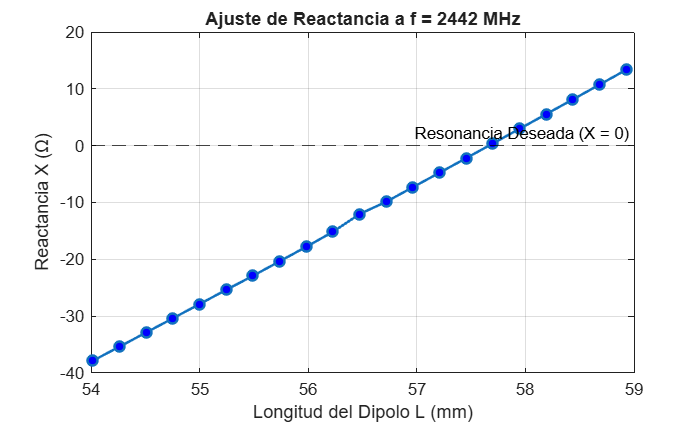


for i = 1:length(L_vector)
    d_temp = dipole('Length', L_vector(i), 'Width', w);
    
    % 1. Reactancia medida exactamente a la frecuencia central (2442 MHz)
    Z_temp = impedance(d_temp, f_central);
    reactancias(i) = imag(Z_temp);
    
    % 2. Búsqueda de la frecuencia exacta donde X = 0 (Frecuencia de Resonancia)
    Z_sweep = impedance(d_temp, f_rang_sweep);
    X_sweep = imag(Z_sweep);
    [~, idx_zero] = min(abs(X_sweep)); % Encuentra el punto más cercano a X = 0
    f_res_vector(i) = f_rang_sweep(idx_zero);
end

% Selección de la longitud óptima donde X se anula en 2442 MHz
[~, idx_opt] = min(abs(reactancias));
L_opt = L_vector(idx_opt);
f_res_opt = f_res_vector(idx_opt);

% Longitud inicial (0.48*lambda) y su frecuencia de resonancia para comparación
L_inicial = 0.48 * lam;
f_res_inicial = f_res_vector(end); 

%% 3. GRÁFICAS DE SINTONIZACIÓN DE RESONANCIA
% Gráfica 1: Reactancia a 2442 MHz vs Longitud
figure('Name', 'Reactancia vs Longitud');
plot(L_vector*1000, reactancias, '-o', 'LineWidth', 1.5, 'MarkerFaceColor', 'b');
yline(0, 'k--', 'Resonancia Deseada (X = 0)');
grid on;
xlabel('Longitud del Dipolo L (mm)');
ylabel('Reactancia X (\Omega)');
title('Ajuste de Reactancia a f = 2442 MHz');

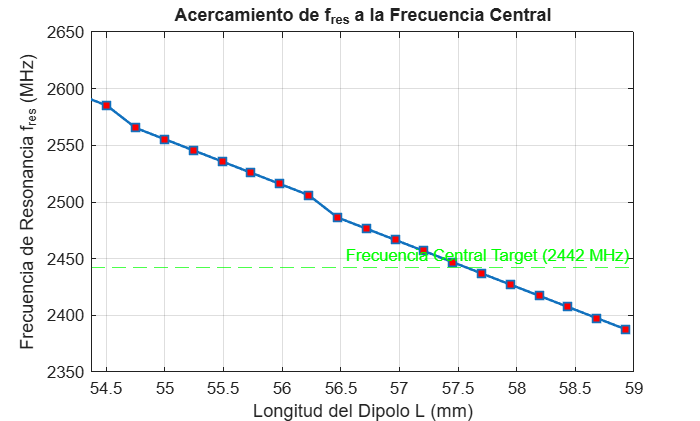


% Gráfica 2: Desplazamiento de la Frecuencia de Resonancia
figure('Name', 'Frecuencia de Resonancia vs Longitud');
plot(L_vector*1000, f_res_vector/1e6, '-s', 'LineWidth', 1.5, 'MarkerFaceColor', 'r');
yline(f_central/1e6, 'g--', 'Frecuencia Central Target (2442 MHz)');
grid on;
xlabel('Longitud del Dipolo L (mm)');
ylabel('Frecuencia de Resonancia f_r_e_s (MHz)');
title('Acercamiento de f_r_e_s a la Frecuencia Central');

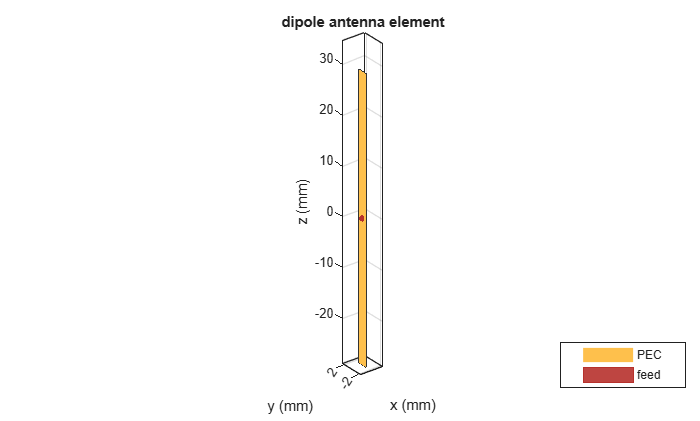


%% 4. ANTENA CON LA LONGITUD OPTIMIZADA
d = dipole('Length', L_opt, 'Width', w);

figure('Name', 'Geometría Optimizada'); show(d);

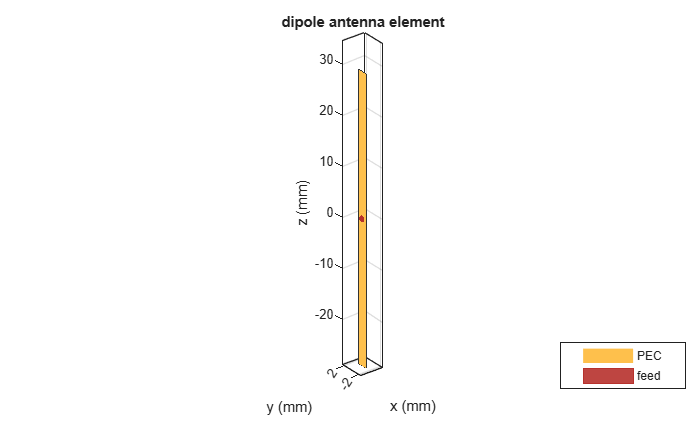

figure('Name', 'Mallado (Mesh)'); mesh(d);

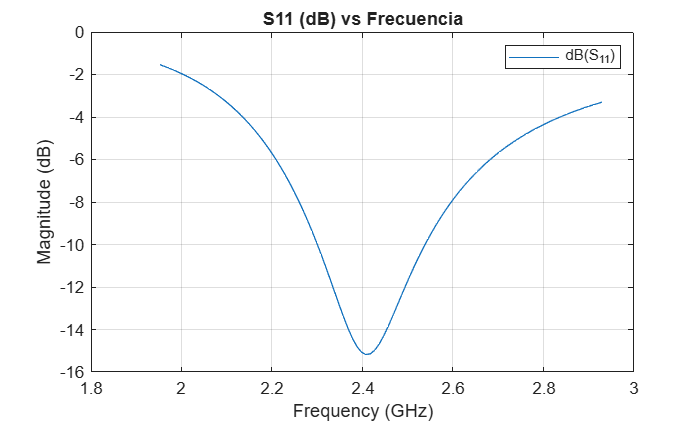


Zin = impedance(d, f_central);

%% 5. S11 Y VSWR (GRÁFICO Y NUMÉRICO)
f_rang = linspace(0.8*f_central, 1.2*f_central, 100);

% Coeficiente de reflexión S11
s = sparameters(d, f_rang);
figure('Name', 'Coeficiente de Reflexión S11');
rfplot(s);
title('S11 (dB) vs Frecuencia');

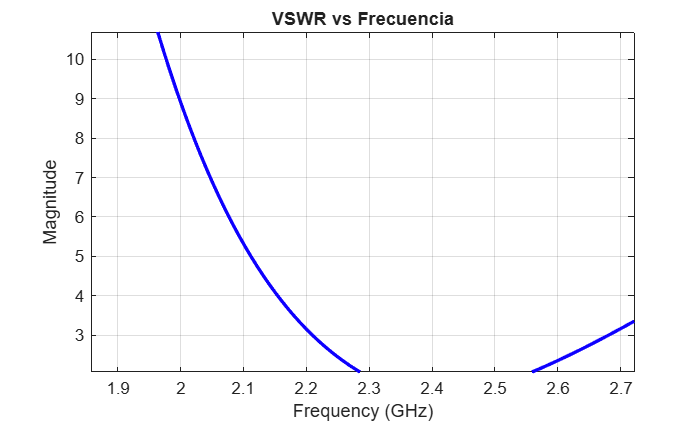


% VSWR Gráfico
figure('Name', 'Curva de VSWR');
vswr(d, f_rang);
title('VSWR vs Frecuencia');

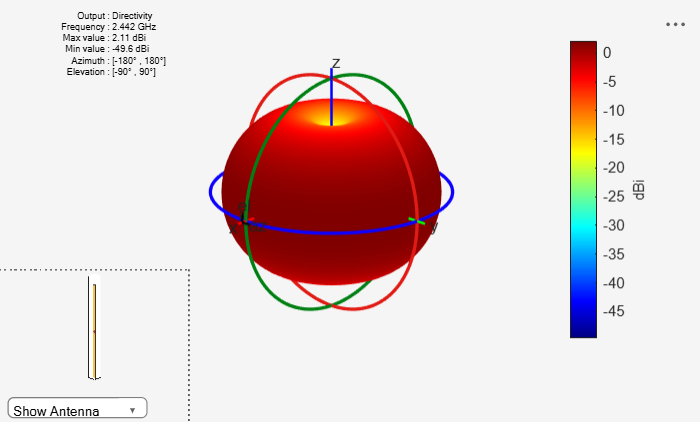


% VSWR Numérico a la frecuencia central
vswr_val = vswr(d, f_central);

%% 6. PATRONES DE RADIACIÓN Y PARÁMETROS
figure('Name', 'Patrón 3D Interactivo'); pattern(d, f_central);

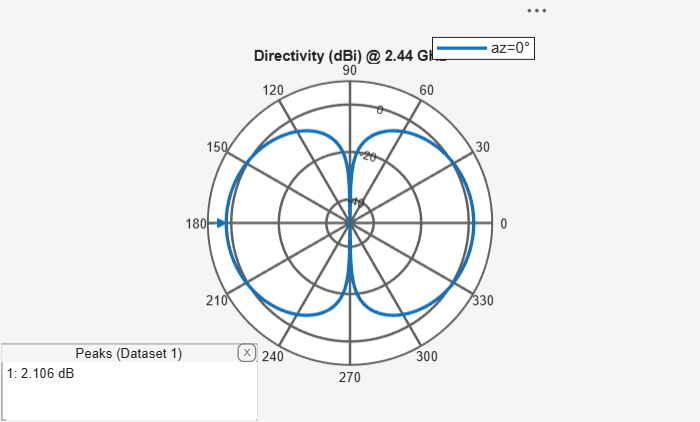

figure('Name', 'Corte Plano E'); patternElevation(d, f_central);

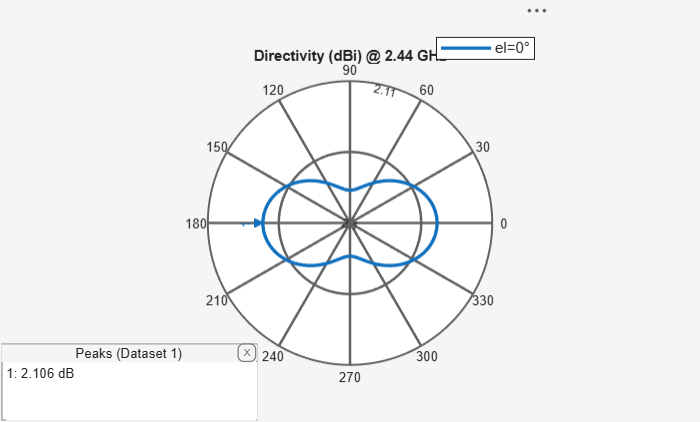

figure('Name', 'Corte Plano H'); patternAzimuth(d, f_central, 0);


% Directividad, Ganancia y Ancho de Haz (HPBW)
D_mat = pattern(d, f_central, 'Type', 'directivity');
D_max = max(D_mat(:));

G_mat = pattern(d, f_central, 'Type', 'gain');
G_max = max(G_mat(:));

bw = beamwidth(d, f_central, 0, 1:360);

%% 7. DESPLIEGUE DE RESULTADOS PARA LA PRESENTACIÓN
fprintf('\n=================================================================\n');

fprintf('        ANÁLISIS DE RESONANCIA Y RESULTADOS DE SIMULACIÓN\n');

        ANÁLISIS DE RESONANCIA Y RESULTADOS DE SIMULACIÓN


fprintf('=================================================================\n');

fprintf(' Frecuencia Central Requerida : %.2f MHz\n', f_central / 1e6);

 Frecuencia Central Requerida : 2442.00 MHz


fprintf(' ---------------------------------------------------------------\n');

 ---------------------------------------------------------------


fprintf(' LONGITUD INICIAL (0.48*λ)    : %.2f mm\n', L_inicial * 1000);

 LONGITUD INICIAL (0.48*λ)    : 58.93 mm


fprintf(' -> Frecuencia Resonancia     : %.2f MHz (Alejada)\n', f_res_inicial / 1e6);

 -> Frecuencia Resonancia     : 2387.73 MHz (Alejada)


fprintf(' ---------------------------------------------------------------\n');

 ---------------------------------------------------------------


fprintf(' LONGITUD OPTIMIZADA (L_opt)  : %.2f mm (Factor: %.4f*λ)\n', L_opt * 1000, L_opt/lam);

 LONGITUD OPTIMIZADA (L_opt)  : 57.70 mm (Factor: 0.4700*λ)


fprintf(' -> Frecuencia Resonancia     : %.2f MHz (¡Sintonizada!)\n', f_res_opt / 1e6);

 -> Frecuencia Resonancia     : 2437.07 MHz (¡Sintonizada!)


fprintf(' ---------------------------------------------------------------\n');

 ---------------------------------------------------------------


fprintf(' Impedancia Zin a 2442 MHz    : %.4f + (%.4fi) Ohms\n', real(Zin), imag(Zin));

 Impedancia Zin a 2442 MHz    : 72.7379 + (0.3776i) Ohms


fprintf(' VSWR Numérico a 2442 MHz     : %.4f\n', vswr_val);

 VSWR Numérico a 2442 MHz     : 1.4548


fprintf(' Directividad Máxima          : %.2f dBi\n', D_max);

 Directividad Máxima          : 2.11 dBi


fprintf(' Ganancia Máxima (G)          : %.2f dBi\n', G_max);

 Ganancia Máxima (G)          : 2.11 dBi


fprintf(' Ancho de Haz (HPBW)          : %.1f deg\n', bw);

 Ancho de Haz (HPBW)          : 80.0 deg
 Ancho de Haz (HPBW)          : 80.0 deg


fprintf('=================================================================\n\n');